# Configure Incremental Learning Options

Prepare an incremental regression learner by specifying a metrics warm-up period, during which the `updateMetricsAndFit` function only fits the model. Specify a metrics window size of 500 observations. Train the model by using SGD, and adjust the SGD batch size, learning rate, and regularization parameter. 

Load the robot arm data set. 

%load robotarm

idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


idxTestAll_batIndex

idxTestAll_batIndex =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


idxTestAll_batIndex1 = (idxTestAll_batIndex == 16)

idxTestAll_batIndex1 = 1×4488 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idxTest

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



find(idxTestAll_batIndex == idxTest(7))

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)))

idxTestAll_test1 =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011



RUL(idxTestAll_test1)

ans =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


test_bat = idxTest(7)

test_bat = 16

RUL_test = RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)))

RUL_test =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


ynorm_RUL_test = ynorm_RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)))

ynorm_RUL_test =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


SOH_test = Cap(idxTestAll(find(idxTestAll_batIndex == test_bat)))

SOH_test =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


ynorm_SOH_test = ynorm_SOH(idxTestAll(find(idxTestAll_batIndex == test_bat)))

ynorm_SOH_test =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791



Ic_test = Ic(idxTestAll(find(idxTestAll_batIndex == test_bat)),:)

Ic_test =     6.0003    6.0001    5.9997    6.0001    5.9999    6.0006    5.9998    4.1998    3.0000    3.0000    3.0000    2.9999    3.0000    3.0001    2.1289    0.9999    1.0000    0.2383         0         0
    6.0008    6.0005    5.9999    5.9998    5.9997    6.0005    5.9999    4.2002    3.0001    3.0000    3.0000    2.9999    3.0000    3.0000    2.1270    1.0000    1.0000    0.2294         0         0
    5.9998    6.0000    6.0006    6.0002    6.0002    5.9997    6.0003    4.1997    3.0000    3.0000    3.0000    2.9999    3.0002    3.0000    2.1257    1.0000    0.9998    0.2293         0         0
    6.0008    6.0002    5.9999    5.9997    6.0007    6.0004    6.0004    4.1998    3.0002    3.0000    3.0000    3.0000    2.9999    3.0000    2.1274    1.0000    1.0000    0.2238         0         0
    6.0008    6.0002    6.0002    6.0003    6.0001    5.9999    5.9998    4.1998    3.0001    3.0000    2.9999    2.9998    3.0000    3.0000    2.1282    1.0000    0.9999    0.2214      

Vd_test = Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:)

Vd_test =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.9999    2.

xnorm_Vd_test = xnorm_Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:)

xnorm_Vd_test =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010


ytrain = ynorm_RUL_test

ytrain =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


Xtrain = xnorm_Vd_test

Xtrain =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010    0.0

Ytrain = RUL_test

Ytrain =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


Ytrain_soh = SOH_test

Ytrain_soh =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


Xtrain = Xtrain(1:315,:);
ytrain = ytrain(1:315,:);
Ytrain = Ytrain(1:315,:);
Ytrain_soh = Ytrain_soh(1:315,:);

idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)));
idxFindAll = find(idxTestAll_batIndex == idxFind);
Y_test_RUL_test1 = Y_test_RUL(idxFindAll);
Y_test_SOH_test1 = Y_test_SOH(idxFindAll);
% Yfit_test_RUL_test1 = Yfit_test_RUL(idxFindAll);


compareTo = Y_test_RUL_test1(1)

idx = idxTestSort(idxSearch) %16

compareTo = 316

% find most similar data
idxTrainValid = [idxTrain idxValid]

idx = 16


count = length(idxTrain) + length(idxValid)

idxTrainValid =     38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25    27    33    53     2    22     8    57    23    55    45     3    17    34    41   109    18     7     9    13    93


idxSel = 0;
diff = 1000;

count = 107

for i=1:count 
    diff_new = abs( ryan4_battery_dataset(idxTrainValid(i)).cycle_life - compareTo );
    if diff_new < diff 
        idxSel = idxTrainValid(i);
        diff = diff_new;
    end
end


matchedRUL = ryan4_battery_dataset(idxSel).cycle_life

matchedRUL = 317

inTrain = any(idxTrain==idxSel)

inTrain = logical
   1



if inTrain
    idxFindSel = idxTest(find(idxTest == idxTestSort(idxSearch)));
    idxFindAllSel = find(idxTestAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
else
    idxFindSel = idxTest(find(idxValid == idxValidSort(idxSearch)));
    idxFindAllSel = find(idxValidAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
end 


ytrainSim = y_test_RUL_Sel1;

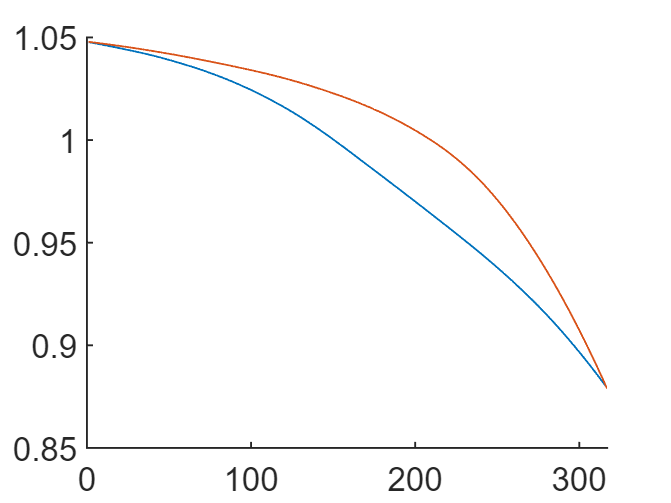


figure, hold on
plot(ryan4_battery_dataset(idx).QDischargeSmooth)
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth)
hold off



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)));
idxFindAll2 = find(idxTestAll_batIndex == idxFind2);
Y_test_RUL_test2 = Y_test_RUL(idxFindAll2);
% Yfit_test_RUL_test2 = Yfit_test_RUL(idxFindAll2);

n = numel(ytrain);

For details on the data set, enter  `Description` at the command line.

Create an incremental linear model for regression. Configure the model as follows:

- Specify the SGD solver.

- Assume that these settings work well for the problem: a ridge regularization parameter value of 0.001, SGD batch size of 20, learning rate of 0.002, and half the width of the epsilon insensitive band for SVM of 0.05.

- Specify that the incremental fitting functions process the raw (unstandardized) predictor data.

- Specify a metrics warm-up period of 1000 observations.

- Specify a metrics window size of 500 observations.

- Track the epsilon insensitive loss, MSE, and mean absolute error (MAE) to measure the performance of the model. The software supports epsilon insensitive loss and MSE. Create an anonymous function that measures the absolute error of each new observation. Create a structure array containing the name `MeanAbsoluteError` and its corresponding function.

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

Mdl = incrementalRegressionLinear(  ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',10, ...
    'Learner','leastsquares', ...
    'Metrics',{ 'mse' })

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'leastsquares'


  Properties, Methods


`Mdl` is an `incrementalRegressionLinear` model object configured for incremental learning without an estimation period.

Fit the incremental model to the data by using the `updateMetricsAndFit` function. At each iteration:

- Simulate a data stream by processing a chunk of 50 observations. Note that the chunk size is different from SGD batch size.

- Overwrite the previous incremental model with a new one fitted to the incoming observations.

- Store the estimated coefficient $\beta_{10}$, the cumulative metrics, and the window metrics to see how they evolve during incremental learning.

% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend    
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    Mdl.Beta;
    Mdl.Bias;
    %ei{j,:} = Mdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    % mae{j,:} = Mdl.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = Mdl.Beta(10);
end

idx =      1     2     3     4     5


idx =      6     7     8     9    10


idx =     11    12    13    14    15


idx =     16    17    18    19    20


idx =     21    22    23    24    25


idx =     26    27    28    29    30


idx =     31    32    33    34    35


idx =     36    37    38    39    40


idx =     41    42    43    44    45


idx =     46    47    48    49    50


idx =     51    52    53    54    55


idx =     56    57    58    59    60


idx =     61    62    63    64    65


idx =     66    67    68    69    70


idx =     71    72    73    74    75


idx =     76    77    78    79    80


idx =     81    82    83    84    85


idx =     86    87    88    89    90


idx =     91    92    93    94    95


idx =     96    97    98    99   100


idx =    101   102   103   104   105


idx =    106   107   108   109   110


idx =    111   112   113   114   115


idx =    116   117   118   119   120


idx =    121   122   123   124   125


idx =    126   127   128   129   130


idx =    131   132   133   134   135


idx =    136   137   138   139   140


idx =    141   142   143   144   145


idx =    146   147   148   149   150


idx = 1×5
   151   152   153   154   155


idx = 1×5
   156   157   158   159   160


idx = 1×5
   161   162   163   164   165


idx = 1×5
   166   167   168   169   170


idx = 1×5
   171   172   173   174   175


idx = 1×5
   176   177   178   179   180


idx = 1×5
   181   182   183   184   185


idx = 1×5
   186   187   188   189   190


idx = 1×5
   191   192   193   194   195


idx = 1×5
   196   197   198   199   200


idx = 1×5
   201   202   203   204   205


idx = 1×5
   206   207   208   209   210


idx = 1×5
   211   212   213   214   215


idx = 1×5
   216   217   218   219   220


idx = 1×5
   221   222   223   224   225


idx = 1×5
   226   227   228   229   230


idx = 1×5
   231   232   233   234   235


idx = 1×5
   236   237   238   239   240


idx = 1×5
   241   242   243   244   245


idx = 1×5
   246   247   248   249   250


idx = 1×5
   251   252   253   254   255


idx = 1×5
   256   257   258   259   260


idx = 1×5
   261   262   263   264   265


idx = 1×5
   266   267   268   269   270


idx = 1×5
   271   272   273   274   275


idx = 1×5
   276   277   278   279   280


idx = 1×5
   281   282   283   284   285


idx = 1×5
   286   287   288   289   290


idx = 1×5
   291   292   293   294   295


idx = 1×5
   296   297   298   299   300


idx = 1×5
   301   302   303   304   305


idx = 1×5
   306   307   308   309   310


idx = 1×5
   311   312   313   314   315


`Mdl` is an `incrementalRegressionLinear` model object trained on all the data in the stream. During incremental learning and after the model is warmed up, `updateMetricsAndFit` checks the performance of the model on the incoming observations, and then fits the model to those observations.

To see how the performance metrics and $\beta_{10}$ evolve during training, plot them on separate tiles.

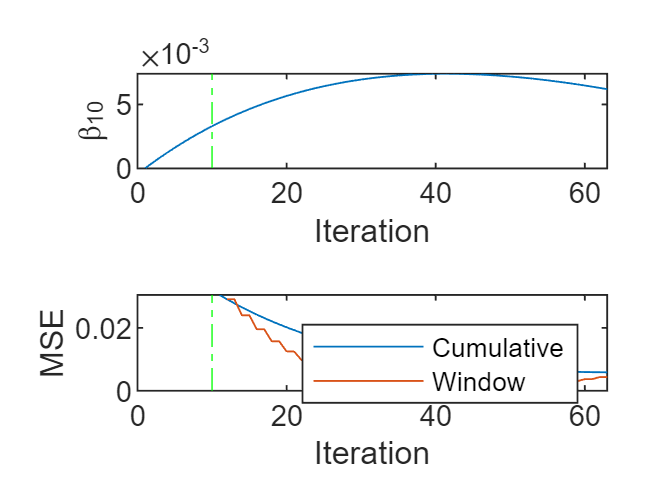

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

The plot suggests that `updateMetricsAndFit` does the following:

- Fit $\beta_{10}$ during all incremental learning iterations.

- Compute the performance metrics after the metrics warm-up period only.

- Compute the cumulative metrics during each iteration.

- Compute the window metrics after processing 500 observations (10 iterations).

*Copyright 2020 The MathWorks, Inc.*

total = length(ytrain)

total = 315

pre = 50;
future = total - pre

future = 265

Xtrain_all = Xtrain ;
ytrain_all = ytrain ;
Ytrain_all = Ytrain ;
Ytrain_SOH_all = Ytrain_soh;

Xtrain_pre = Xtrain(1:pre,:);
ytrain_pre = ytrain(1:pre,:);
Ytrain_pre = Ytrain(1:pre,:);
Ytrain_SOH_pre = Ytrain_soh(1:pre,:);

Xtrain_future = Xtrain(pre+1:end,:);
ytrain_future = ytrain(pre+1:end,:);
Ytrain_future = Ytrain(pre+1:end,:);
Ytrain_SOH_future = Ytrain_soh(pre+1:end,:);

[Mdl1,FitInfo] = fitrlinear(Xtrain_pre,ytrain_pre,"learner","leastsquares")

Mdl1 =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: 0.2473
               Lambda: 0.0200
              Learner: 'leastsquares'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 0.0200
                 Objective: 7.4262e-05
            IterationLimit: 1000
             NumIterations: 8
              GradientNorm: 1.6935e-05
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 7.8861e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'Tolerance on coefficients satisfied.'}
                   History: []
                   FitTime: 0.0041
                    Solver: {'bfgs'}


Mdl1.Beta

ans = 20×1
   -0.0010
   -0.0008
   -0.0008
   -0.0007
   -0.0007
   -0.0006
   -0.0006
   -0.0006
   -0.0005
   -0.0004


Mdl1.Bias

ans = 0.2473

yhat_pre_calc = Xtrain_pre(1,:) * Mdl1.Beta + Mdl1.Bias

yhat_pre_calc = 0.2488

yhat_pre_predict = predict(Mdl1,Xtrain_pre(1,:))

yhat_pre_predict = 0.2488

# 현재까지 학습된 자신의 모델로 과거값을 예측하면 오차가 작다. 그러나 정확하지는 않다.

yhat_pre = predict(Mdl1,Xtrain_pre);


Yhat_pre = yhat_pre * yrate_RUL + ymin_RUL;

rmse_pre = sqrt( mean((Ytrain_pre - Yhat_pre).^2 ) )

rmse_pre = 14.0912

diff_percentage_pre = abs(Ytrain_pre - Yhat_pre)./Ytrain_pre.*100

diff_percentage_pre = 50×1
    7.5688
    7.2981
    7.0129
    6.7337
    6.4467
    6.1506
    5.8544
    5.5538
    5.2625
    4.9647


diff_percentage_avg_pre = mean(diff_percentage_pre,1)

diff_percentage_avg_pre = 4.2072

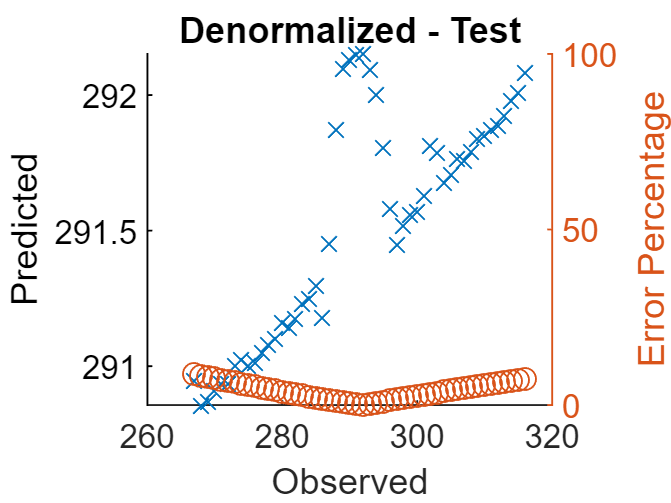

figure
hold on
%plot(Ytrain_pre,Ytrain_pre)
plot(Ytrain_pre,Yhat_pre,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_pre,diff_percentage_pre,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

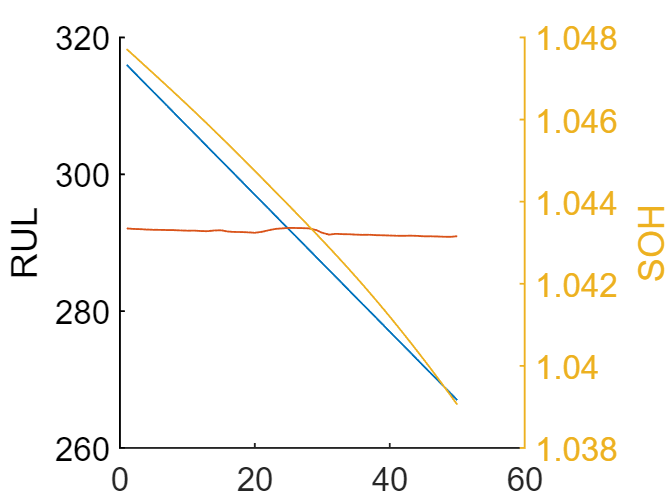


figure, hold on
plot(Ytrain_pre)
plot(Yhat_pre)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Ytrain_SOH_pre)
hold off

# 현재까지 학습된 자신의 모델로 미래를 예측하면 예측오차가 매우 커진다.

yhat_future = predict(Mdl1,Xtrain_future);
Yhat_future = yhat_future*yrate_RUL + ymin_RUL;
rmse_future = sqrt( mean((Ytrain_future - Yhat_future).^2 ) )

rmse_future = 169.4288

diff_percentage_future = abs(Ytrain_future - Yhat_future)./Ytrain_future.*100

diff_percentage_future = 265×1
    9.4088
    9.8447
   10.2698
   10.6840
   11.0979
   11.5013
   11.8947
   12.2201
   12.6004
   13.0168


diff_percentage_avg_future = mean(diff_percentage_future,1)

diff_percentage_avg_future = 454.0499

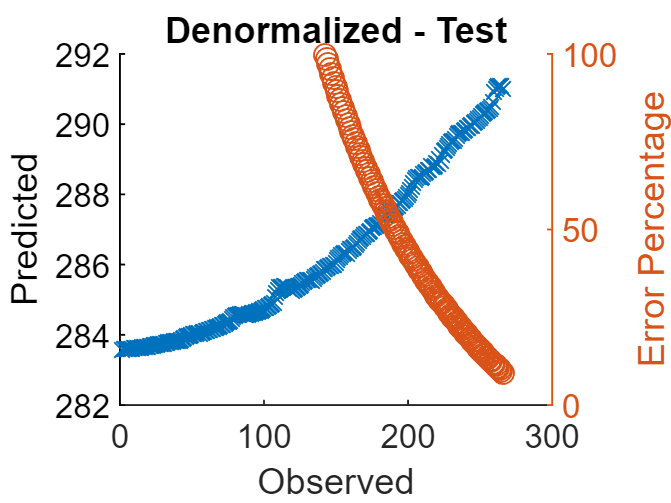

figure
hold on
%plot(Ytrain_future,Ytrain_future)
plot(Ytrain_future,Yhat_future,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_future,diff_percentage_future,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

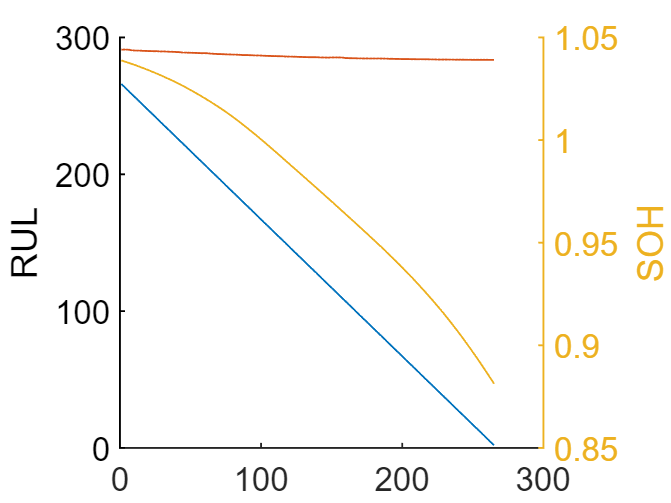


figure, hold on
plot(Ytrain_future)
plot(Yhat_future)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Ytrain_SOH_future)
hold off

# 클라우드에서 현재까지 학습된 모델로 자신을 예측하면 예측오차가 매우 좀 더 작아지지만, 자신의 데이타로 학습한 만큼의 결과가 나오지 않는다.

load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')


yhat_all = predict(mdl_Linear_VdRul_fitrlinear,Xtrain_all);
Yhat_all = yhat_all * yrate_RUL + ymin_RUL;

rmse_all = sqrt( mean((Ytrain_all - Yhat_all).^2 ) )

rmse_all = 56.3081

diff_percentage_all = abs(Ytrain_all - Yhat_all)./Ytrain_all.*100

diff_percentage_all = 315×1
   43.3669
   42.1212
   41.6242
   40.7826
   40.3368
   40.3643
   40.2104
   40.4095
   39.6755
   39.1515


diff_percentage_avg_all = mean(diff_percentage_all,1)

diff_percentage_avg_all = 32.7476

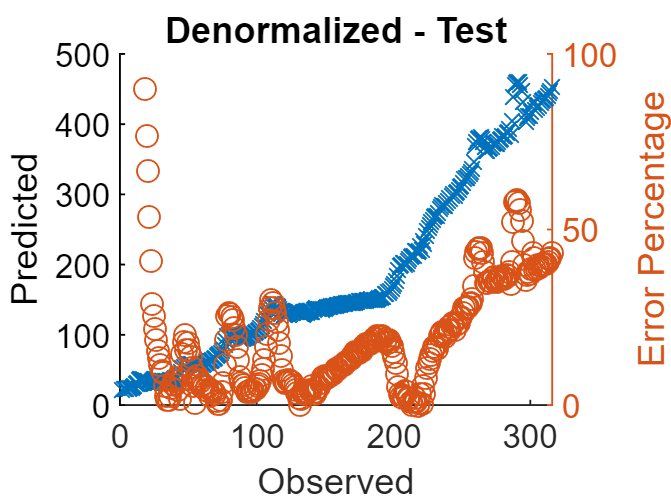

figure
hold on
plot(Ytrain_all,Yhat_all,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

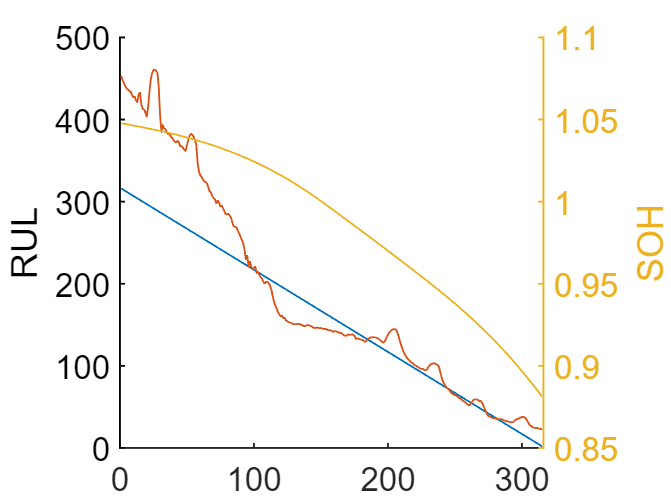



figure, hold on
plot(Y_test_RUL_test1)
plot(Yhat_all)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

yhat = predict(mdl_Linear_VdRul_fitrlinear,Xtrain(1,:))

yhat = 0.3864

mdl_Linear_VdRul_fitrlinear.Beta 

ans = 20×1
   -0.4300
   -0.2471
   -0.0565
    0.0360
    0.1613
    0.3305
    0.4949
    0.5662
    0.4575
    0.2428


mdl_Linear_VdRul_fitrlinear.Bias

ans = -1.0687

yhat_cals = Xtrain(1,:) * mdl_Linear_VdRul_fitrlinear.Beta  +  mdl_Linear_VdRul_fitrlinear.Bias

yhat_cals = 0.3864

## 점진적 학습 - 과거데이타에서 정확한 RUL 안다고 가정하면 러닝레이트를 높이자.


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc

mdl_Linear_VdRul_fitrlinear_inc =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc.Beta'

ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc = updateMetricsAndFit(...
        mdl_Linear_VdRul_fitrlinear_inc,...
        Xtrain(idx,:),...
        ytrain(idx));
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc.Beta'
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp]
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc.Beta(10);
end

idx = 1×5
     1     2     3     4     5


ans = 1×20
   -0.4402   -0.2569   -0.0662    0.0264    0.1518    0.3210    0.4856    0.5569    0.4484    0.2338    0.0415   -0.1009   -0.0854   -0.0113    0.1326   -0.0375    1.0292    0.2708   -0.4946   -0.4823


ans = 5×3
    0.2692    0.2604    0.0088
    0.2684    0.2559    0.0125
    0.2675    0.2534    0.0141
    0.2667    0.2499    0.0167
    0.2658    0.2475    0.0183


idx = 1×5
     6     7     8     9    10


ans = 1×20
   -0.4383   -0.2551   -0.0644    0.0281    0.1535    0.3227    0.4872    0.5585    0.4500    0.2354    0.0431   -0.0994   -0.0839   -0.0099    0.1338   -0.0365    1.0295    0.2708   -0.4946   -0.4823


ans = 5×3
    0.2650    0.2690   -0.0041
    0.2641    0.2674   -0.0033
    0.2632    0.2668   -0.0035
    0.2624    0.2637   -0.0013
    0.2615    0.2611    0.0004


idx = 1×5
    11    12    13    14    15


ans = 1×20
   -0.4385   -0.2553   -0.0646    0.0279    0.1533    0.3225    0.4870    0.5583    0.4498    0.2352    0.0429   -0.0995   -0.0841   -0.0100    0.1337   -0.0366    1.0294    0.2708   -0.4945   -0.4822


ans = 5×3
    0.2607    0.2594    0.0013
    0.2598    0.2554    0.0044
    0.2590    0.2534    0.0056
    0.2581    0.2614   -0.0032
    0.2573    0.2633   -0.0060


idx = 1×5
    16    17    18    19    20


ans = 1×20
   -0.4375   -0.2544   -0.0637    0.0288    0.1541    0.3233    0.4877    0.5591    0.4505    0.2359    0.0437   -0.0988   -0.0833   -0.0094    0.1343   -0.0361    1.0295    0.2708   -0.4945   -0.4822


ans = 5×3
    0.2564    0.2618   -0.0053
    0.2556    0.2571   -0.0015
    0.2547    0.2568   -0.0021
    0.2538    0.2538    0.0000
    0.2530    0.2492    0.0038


idx = 1×5
    21    22    23    24    25


ans = 1×20
   -0.4404   -0.2572   -0.0665    0.0260    0.1514    0.3206    0.4850    0.5564    0.4479    0.2334    0.0412   -0.1012   -0.0857   -0.0116    0.1322   -0.0377    1.0286    0.2707   -0.4944   -0.4821


ans = 5×3
    0.2521    0.2226    0.0295
    0.2513    0.2381    0.0131
    0.2504    0.2513   -0.0009
    0.2496    0.2576   -0.0081
    0.2487    0.2612   -0.0124


idx = 1×5
    26    27    28    29    30


ans = 1×20
   -0.4405   -0.2572   -0.0666    0.0259    0.1513    0.3204    0.4849    0.5562    0.4477    0.2332    0.0411   -0.1013   -0.0858   -0.0117    0.1321   -0.0378    1.0285    0.2707   -0.4944   -0.4821


ans = 5×3
    0.2479    0.2600   -0.0122
    0.2470    0.2585   -0.0115
    0.2462    0.2565   -0.0103
    0.2453    0.2413    0.0040
    0.2444    0.2127    0.0317


idx = 1×5
    31    32    33    34    35


ans = 1×20
   -0.4365   -0.2534   -0.0628    0.0296    0.1549    0.3240    0.4884    0.5597    0.4512    0.2367    0.0445   -0.0980   -0.0826   -0.0087    0.1349   -0.0357    1.0292    0.2707   -0.4943   -0.4820


ans = 5×3
    0.2436    0.2441   -0.0005
    0.2427    0.2512   -0.0085
    0.2419    0.2478   -0.0059
    0.2410    0.2470   -0.0060
    0.2402    0.2436   -0.0035


idx = 1×5
    36    37    38    39    40


ans = 1×20
   -0.4366   -0.2536   -0.0630    0.0295    0.1547    0.3238    0.4882    0.5595    0.4510    0.2365    0.0443   -0.0981   -0.0827   -0.0088    0.1347   -0.0358    1.0290    0.2707   -0.4943   -0.4820


ans = 5×3
    0.2393    0.2393    0.0000
    0.2385    0.2406   -0.0022
    0.2376    0.2370    0.0006
    0.2368    0.2357    0.0010
    0.2359    0.2336    0.0023


idx = 1×5
    41    42    43    44    45


ans = 1×20
   -0.4363   -0.2533   -0.0628    0.0297    0.1549    0.3240    0.4884    0.5596    0.4511    0.2367    0.0445   -0.0979   -0.0825   -0.0086    0.1349   -0.0356    1.0290    0.2706   -0.4942   -0.4819


ans = 5×3
    0.2350    0.2344    0.0007
    0.2342    0.2338    0.0004
    0.2333    0.2354   -0.0021
    0.2325    0.2339   -0.0015
    0.2316    0.2300    0.0016


idx = 1×5
    46    47    48    49    50


ans = 1×20
   -0.4362   -0.2532   -0.0627    0.0298    0.1550    0.3241    0.4884    0.5597    0.4512    0.2367    0.0446   -0.0978   -0.0824   -0.0086    0.1349   -0.0356    1.0289    0.2706   -0.4942   -0.4819


ans = 5×3
    0.2308    0.2307    0.0000
    0.2299    0.2295    0.0004
    0.2291    0.2271    0.0019
    0.2282    0.2261    0.0021
    0.2274    0.2318   -0.0044


idx = 1×5
    51    52    53    54    55


ans = 1×20
   -0.4376   -0.2546   -0.0641    0.0284    0.1536    0.3227    0.4870    0.5583    0.4498    0.2354    0.0433   -0.0991   -0.0836   -0.0097    0.1339   -0.0364    1.0285    0.2706   -0.4941   -0.4818


ans = 5×3
    0.2265    0.2190    0.0075
    0.2256    0.2232    0.0024
    0.2248    0.2250   -0.0003
    0.2239    0.2242   -0.0002
    0.2231    0.2223    0.0008


idx = 1×5
    56    57    58    59    60


ans = 1×20
   -0.4357   -0.2527   -0.0622    0.0302    0.1554    0.3244    0.4887    0.5600    0.4515    0.2371    0.0450   -0.0974   -0.0821   -0.0082    0.1352   -0.0354    1.0287    0.2705   -0.4941   -0.4818


ans = 5×3
    0.2222    0.2421   -0.0198
    0.2214    0.2371   -0.0157
    0.2205    0.2190    0.0016
    0.2197    0.2096    0.0100
    0.2188    0.2058    0.0130


idx = 1×5
    61    62    63    64    65


ans = 1×20
   -0.4342   -0.2513   -0.0609    0.0315    0.1567    0.3257    0.4900    0.5612    0.4527    0.2383    0.0462   -0.0962   -0.0809   -0.0071    0.1362   -0.0346    1.0288    0.2705   -0.4940   -0.4817


ans = 5×3
    0.2179    0.2218   -0.0038
    0.2171    0.2188   -0.0018
    0.2162    0.2170   -0.0008
    0.2154    0.2164   -0.0010
    0.2145    0.2148   -0.0003


idx = 1×5
    66    67    68    69    70


ans = 1×20
   -0.4335   -0.2507   -0.0602    0.0321    0.1573    0.3263    0.4905    0.5617    0.4533    0.2389    0.0468   -0.0957   -0.0804   -0.0066    0.1366   -0.0343    1.0288    0.2705   -0.4940   -0.4817


ans = 5×3
    0.2137    0.2185   -0.0048
    0.2128    0.2147   -0.0018
    0.2120    0.2130   -0.0010
    0.2111    0.2093    0.0018
    0.2103    0.2074    0.0028


idx = 1×5
    71    72    73    74    75


ans = 1×20
   -0.4330   -0.2502   -0.0598    0.0325    0.1577    0.3266    0.4909    0.5621    0.4536    0.2392    0.0471   -0.0953   -0.0800   -0.0063    0.1369   -0.0340    1.0287    0.2705   -0.4939   -0.4816


ans = 5×3
    0.2094    0.2111   -0.0017
    0.2085    0.2070    0.0015
    0.2077    0.2101   -0.0024
    0.2068    0.2080   -0.0012
    0.2060    0.2039    0.0021


idx = 1×5
    76    77    78    79    80


ans = 1×20
   -0.4326   -0.2499   -0.0595    0.0329    0.1580    0.3269    0.4912    0.5623    0.4539    0.2395    0.0474   -0.0950   -0.0797   -0.0060    0.1371   -0.0339    1.0287    0.2704   -0.4939   -0.4816


ans = 5×3
    0.2051    0.2091   -0.0039
    0.2043    0.2063   -0.0020
    0.2034    0.2031    0.0004
    0.2026    0.1998    0.0027
    0.2017    0.2002    0.0015


idx = 1×5
    81    82    83    84    85


ans = 1×20
   -0.4321   -0.2495   -0.0591    0.0332    0.1584    0.3273    0.4915    0.5626    0.4542    0.2398    0.0478   -0.0947   -0.0794   -0.0057    0.1373   -0.0337    1.0286    0.2704   -0.4938   -0.4815


ans = 5×3
    0.2009    0.2052   -0.0044
    0.2000    0.2033   -0.0033
    0.1991    0.2010   -0.0018
    0.1983    0.1956    0.0027
    0.1974    0.1920    0.0054


idx = 1×5
    86    87    88    89    90


ans = 1×20
   -0.4314   -0.2488   -0.0584    0.0339    0.1590    0.3279    0.4920    0.5632    0.4547    0.2404    0.0483   -0.0941   -0.0788   -0.0052    0.1378   -0.0333    1.0286    0.2704   -0.4938   -0.4815


ans = 5×3
    0.1966    0.1999   -0.0033
    0.1957    0.1991   -0.0034
    0.1949    0.1959   -0.0010
    0.1940    0.1927    0.0013
    0.1932    0.1896    0.0036


idx = 1×5
    91    92    93    94    95


ans = 1×20
   -0.4300   -0.2475   -0.0572    0.0351    0.1602    0.3290    0.4932    0.5643    0.4558    0.2415    0.0494   -0.0930   -0.0778   -0.0042    0.1386   -0.0327    1.0286    0.2704   -0.4937   -0.4815


ans = 5×3
    0.1923    0.2017   -0.0094
    0.1915    0.1981   -0.0067
    0.1906    0.1917   -0.0011
    0.1897    0.1820    0.0077
    0.1889    0.1853    0.0036


idx = 1×5
    96    97    98    99   100


ans = 1×20
   -0.4289   -0.2464   -0.0562    0.0361    0.1612    0.3300    0.4941    0.5652    0.4568    0.2424    0.0504   -0.0921   -0.0769   -0.0034    0.1393   -0.0322    1.0285    0.2703   -0.4937   -0.4814


ans = 5×3
    0.1880    0.1878    0.0003
    0.1872    0.1921   -0.0049
    0.1863    0.1864   -0.0001
    0.1855    0.1844    0.0011
    0.1846    0.1856   -0.0009


idx = 1×5
   101   102   103   104   105


ans = 1×20
   -0.4287   -0.2463   -0.0560    0.0362    0.1613    0.3301    0.4942    0.5653    0.4568    0.2425    0.0505   -0.0919   -0.0768   -0.0033    0.1394   -0.0322    1.0284    0.2703   -0.4936   -0.4814


ans = 5×3
    0.1838    0.1883   -0.0046
    0.1829    0.1818    0.0011
    0.1821    0.1823   -0.0003
    0.1812    0.1801    0.0011
    0.1803    0.1777    0.0026


idx = 1×5
   106   107   108   109   110


ans = 1×20
   -0.4282   -0.2458   -0.0556    0.0366    0.1617    0.3305    0.4945    0.5656    0.4572    0.2429    0.0508   -0.0916   -0.0764   -0.0030    0.1397   -0.0320    1.0284    0.2703   -0.4936   -0.4813


ans = 5×3
    0.1795    0.1813   -0.0018
    0.1786    0.1775    0.0011
    0.1778    0.1759    0.0019
    0.1769    0.1777   -0.0008
    0.1761    0.1779   -0.0018


idx = 1×5
   111   112   113   114   115


ans = 1×20
   -0.4277   -0.2453   -0.0551    0.0371    0.1621    0.3309    0.4950    0.5660    0.4576    0.2433    0.0513   -0.0911   -0.0760   -0.0026    0.1400   -0.0317    1.0283    0.2703   -0.4935   -0.4813


ans = 5×3
    0.1752    0.1822   -0.0070
    0.1744    0.1799   -0.0055
    0.1735    0.1756   -0.0021
    0.1726    0.1688    0.0039
    0.1718    0.1626    0.0091


idx = 1×5
   116   117   118   119   120


ans = 1×20
   -0.4261   -0.2439   -0.0537    0.0385    0.1635    0.3322    0.4963    0.5673    0.4589    0.2446    0.0525   -0.0899   -0.0748   -0.0015    0.1409   -0.0311    1.0282    0.2702   -0.4935   -0.4812


ans = 5×3
    0.1709    0.1764   -0.0055
    0.1701    0.1734   -0.0033
    0.1692    0.1697   -0.0005
    0.1684    0.1671    0.0013
    0.1675    0.1653    0.0023


idx = 1×5
   121   122   123   124   125


ans = 1×20
   -0.4259   -0.2436   -0.0535    0.0387    0.1637    0.3324    0.4964    0.5674    0.4590    0.2447    0.0527   -0.0897   -0.0747   -0.0014    0.1410   -0.0311    1.0281    0.2702   -0.4934   -0.4812


ans = 5×3
    0.1667    0.1681   -0.0014
    0.1658    0.1656    0.0002
    0.1650    0.1660   -0.0011
    0.1641    0.1630    0.0011
    0.1632    0.1622    0.0010


idx = 1×5
   126   127   128   129   130


ans = 1×20
   -0.4258   -0.2436   -0.0535    0.0387    0.1637    0.3324    0.4964    0.5674    0.4590    0.2447    0.0527   -0.0897   -0.0746   -0.0014    0.1410   -0.0310    1.0280    0.2702   -0.4934   -0.4811


ans = 5×3
    0.1624    0.1615    0.0009
    0.1615    0.1614    0.0001
    0.1607    0.1607   -0.0000
    0.1598    0.1597    0.0001
    0.1590    0.1596   -0.0006


idx = 1×5
   131   132   133   134   135


ans = 1×20
   -0.4261   -0.2438   -0.0537    0.0385    0.1634    0.3321    0.4961    0.5671    0.4587    0.2445    0.0525   -0.0899   -0.0749   -0.0016    0.1408   -0.0311    1.0279    0.2702   -0.4933   -0.4811


ans = 5×3
    0.1581    0.1559    0.0022
    0.1573    0.1562    0.0010
    0.1564    0.1567   -0.0003
    0.1556    0.1560   -0.0005
    0.1547    0.1556   -0.0009


idx = 1×5
   136   137   138   139   140


ans = 1×20
   -0.4262   -0.2440   -0.0539    0.0382    0.1632    0.3318    0.4958    0.5668    0.4584    0.2442    0.0523   -0.0901   -0.0750   -0.0017    0.1407   -0.0312    1.0278    0.2701   -0.4933   -0.4810


ans = 5×3
    0.1538    0.1524    0.0014
    0.1530    0.1513    0.0017
    0.1521    0.1514    0.0008
    0.1513    0.1520   -0.0007
    0.1504    0.1522   -0.0018


idx = 1×5
   141   142   143   144   145


ans = 1×20
   -0.4265   -0.2443   -0.0542    0.0380    0.1629    0.3316    0.4955    0.5666    0.4582    0.2440    0.0521   -0.0903   -0.0752   -0.0019    0.1405   -0.0313    1.0277    0.2701   -0.4932   -0.4810


ans = 5×3
    0.1496    0.1489    0.0007
    0.1487    0.1483    0.0005
    0.1479    0.1478    0.0000
    0.1470    0.1470    0.0000
    0.1462    0.1460    0.0002


idx = 1×5
   146   147   148   149   150


ans = 1×20
   -0.4267   -0.2445   -0.0544    0.0378    0.1627    0.3313    0.4953    0.5663    0.4579    0.2438    0.0518   -0.0905   -0.0754   -0.0021    0.1404   -0.0313    1.0276    0.2701   -0.4932   -0.4809


ans = 5×3
    0.1453    0.1435    0.0018
    0.1444    0.1436    0.0009
    0.1436    0.1435    0.0001
    0.1427    0.1431   -0.0004
    0.1419    0.1431   -0.0012


idx = 1×5
   151   152   153   154   155


ans = 1×20
   -0.4269   -0.2447   -0.0546    0.0375    0.1624    0.3311    0.4950    0.5660    0.4576    0.2435    0.0516   -0.0907   -0.0756   -0.0023    0.1402   -0.0314    1.0275    0.2700   -0.4931   -0.4809


ans = 5×3
    0.1410    0.1396    0.0014
    0.1402    0.1393    0.0009
    0.1393    0.1392    0.0002
    0.1385    0.1390   -0.0005
    0.1376    0.1383   -0.0007


idx = 1×5
   156   157   158   159   160


ans = 1×20
   -0.4270   -0.2448   -0.0548    0.0374    0.1622    0.3309    0.4948    0.5658    0.4574    0.2433    0.0515   -0.0908   -0.0757   -0.0024    0.1401   -0.0314    1.0274    0.2700   -0.4931   -0.4808


ans = 5×3
    0.1368    0.1354    0.0014
    0.1359    0.1355    0.0004
    0.1350    0.1350    0.0000
    0.1342    0.1338    0.0004
    0.1333    0.1344   -0.0011


idx = 1×5
   161   162   163   164   165


ans = 1×20
   -0.4272   -0.2450   -0.0550    0.0371    0.1620    0.3306    0.4945    0.5655    0.4572    0.2431    0.0513   -0.0910   -0.0759   -0.0026    0.1399   -0.0314    1.0273    0.2700   -0.4930   -0.4808


ans = 5×3
    0.1325    0.1316    0.0009
    0.1316    0.1310    0.0007
    0.1308    0.1306    0.0002
    0.1299    0.1298    0.0001
    0.1291    0.1298   -0.0008


idx = 1×5
   166   167   168   169   170


ans = 1×20
   -0.4273   -0.2451   -0.0551    0.0370    0.1619    0.3305    0.4944    0.5654    0.4570    0.2430    0.0512   -0.0911   -0.0760   -0.0026    0.1399   -0.0315    1.0272    0.2700   -0.4930   -0.4807


ans = 5×3
    0.1282    0.1277    0.0005
    0.1274    0.1261    0.0013
    0.1265    0.1258    0.0007
    0.1256    0.1256    0.0000
    0.1248    0.1265   -0.0018


idx = 1×5
   171   172   173   174   175


ans = 1×20
   -0.4276   -0.2455   -0.0555    0.0366    0.1615    0.3301    0.4940    0.5650    0.4566    0.2426    0.0508   -0.0914   -0.0763   -0.0029    0.1397   -0.0315    1.0270    0.2699   -0.4929   -0.4807


ans = 5×3
    0.1239    0.1222    0.0017
    0.1231    0.1220    0.0011
    0.1222    0.1223   -0.0001
    0.1214    0.1223   -0.0009
    0.1205    0.1210   -0.0005


idx = 1×5
   176   177   178   179   180


ans = 1×20
   -0.4276   -0.2454   -0.0555    0.0367    0.1615    0.3301    0.4939    0.5649    0.4566    0.2426    0.0508   -0.0914   -0.0762   -0.0029    0.1397   -0.0315    1.0269    0.2699   -0.4929   -0.4806


ans = 5×3
    0.1197    0.1180    0.0017
    0.1188    0.1185    0.0003
    0.1179    0.1180   -0.0000
    0.1171    0.1176   -0.0005
    0.1162    0.1172   -0.0009


idx = 1×5
   181   182   183   184   185


ans = 1×20
   -0.4277   -0.2456   -0.0557    0.0365    0.1613    0.3298    0.4937    0.5647    0.4564    0.2424    0.0507   -0.0915   -0.0764   -0.0030    0.1395   -0.0315    1.0268    0.2699   -0.4928   -0.4806


ans = 5×3
    0.1154    0.1138    0.0016
    0.1145    0.1134    0.0011
    0.1137    0.1122    0.0015
    0.1128    0.1133   -0.0005
    0.1120    0.1148   -0.0028


idx = 1×5
   186   187   188   189   190


ans = 1×20
   -0.4284   -0.2462   -0.0563    0.0358    0.1607    0.3292    0.4930    0.5640    0.4557    0.2418    0.0501   -0.0921   -0.0769   -0.0035    0.1392   -0.0316    1.0267    0.2699   -0.4928   -0.4805


ans = 5×3
    0.1111    0.1086    0.0025
    0.1103    0.1093    0.0010
    0.1094    0.1092    0.0002
    0.1085    0.1094   -0.0009
    0.1077    0.1090   -0.0013


idx = 1×5
   191   192   193   194   195


ans = 1×20
   -0.4285   -0.2464   -0.0565    0.0356    0.1605    0.3290    0.4928    0.5638    0.4555    0.2416    0.0499   -0.0922   -0.0770   -0.0036    0.1391   -0.0316    1.0266    0.2698   -0.4927   -0.4805


ans = 5×3
    0.1068    0.1065    0.0004
    0.1060    0.1060   -0.0000
    0.1051    0.1052   -0.0000
    0.1043    0.1043    0.0000
    0.1034    0.1029    0.0005


idx = 1×5
   196   197   198   199   200


ans = 1×20
   -0.4288   -0.2467   -0.0568    0.0353    0.1601    0.3286    0.4924    0.5634    0.4552    0.2413    0.0496   -0.0925   -0.0773   -0.0038    0.1389   -0.0316    1.0265    0.2698   -0.4927   -0.4804


ans = 5×3
    0.1026    0.0978    0.0048
    0.1017    0.0974    0.0043
    0.1009    0.0998    0.0011
    0.1000    0.1027   -0.0027
    0.0991    0.1056   -0.0065


idx = 1×5
   201   202   203   204   205


ans = 1×20
   -0.4300   -0.2479   -0.0580    0.0342    0.1590    0.3275    0.4913    0.5623    0.4540    0.2402    0.0486   -0.0935   -0.0782   -0.0047    0.1383   -0.0317    1.0264    0.2698   -0.4926   -0.4804


ans = 5×3
    0.0983    0.0939    0.0044
    0.0974    0.0952    0.0023
    0.0966    0.0965    0.0000
    0.0957    0.0971   -0.0013
    0.0949    0.0972   -0.0023


idx = 1×5
   206   207   208   209   210


ans = 1×20
   -0.4297   -0.2475   -0.0577    0.0344    0.1592    0.3277    0.4915    0.5625    0.4543    0.2404    0.0488   -0.0932   -0.0780   -0.0045    0.1384   -0.0317    1.0263    0.2697   -0.4926   -0.4803


ans = 5×3
    0.0940    0.1002   -0.0062
    0.0932    0.0969   -0.0038
    0.0923    0.0926   -0.0003
    0.0915    0.0879    0.0035
    0.0906    0.0836    0.0070


idx = 1×5
   211   212   213   214   215


ans = 1×20
   -0.4284   -0.2463   -0.0565    0.0356    0.1604    0.3288    0.4926    0.5635    0.4553    0.2415    0.0499   -0.0922   -0.0771   -0.0037    0.1389   -0.0316    1.0262    0.2697   -0.4925   -0.4803


ans = 5×3
    0.0897    0.0934   -0.0036
    0.0889    0.0900   -0.0011
    0.0880    0.0875    0.0005
    0.0872    0.0852    0.0020
    0.0863    0.0835    0.0029


idx = 1×5
   216   217   218   219   220


ans = 1×20
   -0.4280   -0.2459   -0.0561    0.0360    0.1607    0.3291    0.4929    0.5638    0.4556    0.2418    0.0502   -0.0919   -0.0768   -0.0034    0.1390   -0.0316    1.0261    0.2697   -0.4925   -0.4803


ans = 5×3
    0.0855    0.0862   -0.0007
    0.0846    0.0847   -0.0000
    0.0838    0.0837    0.0001
    0.0829    0.0824    0.0005
    0.0821    0.0811    0.0009


idx = 1×5
   221   222   223   224   225


ans = 1×20
   -0.4279   -0.2458   -0.0561    0.0360    0.1608    0.3292    0.4929    0.5638    0.4556    0.2418    0.0502   -0.0919   -0.0767   -0.0034    0.1390   -0.0316    1.0260    0.2697   -0.4924   -0.4802


ans = 5×3
    0.0812    0.0812    0.0000
    0.0803    0.0802    0.0001
    0.0795    0.0791    0.0004
    0.0786    0.0782    0.0004
    0.0778    0.0781   -0.0003


idx = 1×5
   226   227   228   229   230


ans = 1×20
   -0.4280   -0.2460   -0.0563    0.0358    0.1605    0.3289    0.4926    0.5636    0.4554    0.2416    0.0500   -0.0920   -0.0769   -0.0035    0.1389   -0.0316    1.0259    0.2696   -0.4924   -0.4802


ans = 5×3
    0.0769    0.0754    0.0015
    0.0761    0.0746    0.0014
    0.0752    0.0740    0.0012
    0.0744    0.0744   -0.0001
    0.0735    0.0772   -0.0037


idx = 1×5
   231   232   233   234   235


ans = 1×20
   -0.4289   -0.2468   -0.0571    0.0350    0.1597    0.3281    0.4918    0.5627    0.4546    0.2408    0.0493   -0.0927   -0.0775   -0.0041    0.1387   -0.0316    1.0258    0.2696   -0.4923   -0.4801


ans = 5×3
    0.0726    0.0693    0.0034
    0.0718    0.0709    0.0009
    0.0709    0.0713   -0.0003
    0.0701    0.0717   -0.0016
    0.0692    0.0714   -0.0022


idx = 1×5
   236   237   238   239   240


ans = 1×20
   -0.4287   -0.2467   -0.0570    0.0351    0.1598    0.3281    0.4918    0.5627    0.4546    0.2409    0.0494   -0.0926   -0.0774   -0.0040    0.1387   -0.0316    1.0257    0.2696   -0.4923   -0.4801


ans = 5×3
    0.0684    0.0715   -0.0032
    0.0675    0.0707   -0.0031
    0.0667    0.0691   -0.0024
    0.0658    0.0635    0.0023
    0.0650    0.0578    0.0071


idx = 1×5
   241   242   243   244   245


ans = 1×20
   -0.4275   -0.2456   -0.0559    0.0362    0.1609    0.3292    0.4928    0.5637    0.4556    0.2419    0.0503   -0.0917   -0.0766   -0.0034    0.1389   -0.0316    1.0256    0.2696   -0.4922   -0.4800


ans = 5×3
    0.0641    0.0662   -0.0021
    0.0632    0.0637   -0.0004
    0.0624    0.0612    0.0012
    0.0615    0.0597    0.0018
    0.0607    0.0584    0.0023


idx = 1×5
   246   247   248   249   250


ans = 1×20
   -0.4271   -0.2452   -0.0555    0.0365    0.1612    0.3295    0.4931    0.5640    0.4558    0.2421    0.0506   -0.0914   -0.0763   -0.0032    0.1389   -0.0316    1.0255    0.2695   -0.4922   -0.4800


ans = 5×3
    0.0598    0.0607   -0.0009
    0.0590    0.0587    0.0003
    0.0581    0.0576    0.0006
    0.0573    0.0565    0.0007
    0.0564    0.0556    0.0008


idx = 1×5
   251   252   253   254   255


ans = 1×20
   -0.4270   -0.2451   -0.0555    0.0365    0.1612    0.3295    0.4931    0.5640    0.4559    0.2422    0.0507   -0.0914   -0.0763   -0.0031    0.1389   -0.0316    1.0254    0.2695   -0.4921   -0.4799


ans = 5×3
    0.0556    0.0562   -0.0006
    0.0547    0.0547    0.0000
    0.0538    0.0532    0.0006
    0.0530    0.0529    0.0001
    0.0521    0.0516    0.0005


idx = 1×5
   256   257   258   259   260


ans = 1×20
   -0.4268   -0.2450   -0.0554    0.0366    0.1613    0.3296    0.4932    0.5640    0.4559    0.2422    0.0508   -0.0913   -0.0762   -0.0031    0.1389   -0.0316    1.0253    0.2695   -0.4921   -0.4799


ans = 5×3
    0.0513    0.0514   -0.0001
    0.0504    0.0508   -0.0004
    0.0496    0.0494    0.0002
    0.0487    0.0483    0.0004
    0.0479    0.0471    0.0008


idx = 1×5
   261   262   263   264   265


ans = 1×20
   -0.4273   -0.2454   -0.0558    0.0362    0.1608    0.3291    0.4927    0.5636    0.4555    0.2418    0.0504   -0.0916   -0.0765   -0.0033    0.1388   -0.0316    1.0252    0.2695   -0.4920   -0.4798


ans = 5×3
    0.0470    0.0416    0.0054
    0.0462    0.0440    0.0021
    0.0453    0.0461   -0.0008
    0.0444    0.0475   -0.0031
    0.0436    0.0479   -0.0043


idx = 1×5
   266   267   268   269   270


ans = 1×20
   -0.4277   -0.2459   -0.0563    0.0357    0.1604    0.3286    0.4922    0.5631    0.4550    0.2414    0.0500   -0.0920   -0.0769   -0.0036    0.1388   -0.0316    1.0251    0.2694   -0.4920   -0.4798


ans = 5×3
    0.0427    0.0425    0.0003
    0.0419    0.0423   -0.0004
    0.0410    0.0405    0.0005
    0.0402    0.0412   -0.0011
    0.0393    0.0394   -0.0001


idx = 1×5
   271   272   273   274   275


ans = 1×20
   -0.4271   -0.2453   -0.0557    0.0362    0.1609    0.3291    0.4926    0.5635    0.4554    0.2418    0.0504   -0.0916   -0.0765   -0.0033    0.1388   -0.0316    1.0250    0.2694   -0.4919   -0.4797


ans = 5×3
    0.0385    0.0428   -0.0043
    0.0376    0.0389   -0.0013
    0.0368    0.0360    0.0008
    0.0359    0.0328    0.0031
    0.0350    0.0308    0.0043


idx = 1×5
   276   277   278   279   280


ans = 1×20
   -0.4268   -0.2450   -0.0555    0.0365    0.1611    0.3293    0.4929    0.5637    0.4556    0.2420    0.0506   -0.0913   -0.0763   -0.0032    0.1388   -0.0316    1.0249    0.2694   -0.4919   -0.4797


ans = 5×3
    0.0342    0.0335    0.0007
    0.0333    0.0324    0.0009
    0.0325    0.0319    0.0006
    0.0316    0.0315    0.0002
    0.0308    0.0313   -0.0005


idx = 1×5
   281   282   283   284   285


ans = 1×20
   -0.4270   -0.2452   -0.0556    0.0363    0.1609    0.3291    0.4926    0.5635    0.4554    0.2418    0.0504   -0.0915   -0.0764   -0.0033    0.1388   -0.0316    1.0248    0.2693   -0.4918   -0.4796


ans = 5×3
    0.0299    0.0285    0.0014
    0.0291    0.0286    0.0004
    0.0282    0.0281    0.0001
    0.0274    0.0281   -0.0007
    0.0265    0.0282   -0.0017


idx = 1×5
   286   287   288   289   290


ans = 1×20
   -0.4272   -0.2454   -0.0559    0.0361    0.1607    0.3289    0.4924    0.5632    0.4551    0.2416    0.0503   -0.0916   -0.0765   -0.0033    0.1387   -0.0316    1.0247    0.2693   -0.4918   -0.4796


ans = 5×3
    0.0256    0.0250    0.0007
    0.0248    0.0245    0.0003
    0.0239    0.0240   -0.0001
    0.0231    0.0236   -0.0005
    0.0222    0.0233   -0.0011


idx = 1×5
   291   292   293   294   295


ans = 1×20
   -0.4274   -0.2457   -0.0562    0.0358    0.1604    0.3285    0.4920    0.5629    0.4548    0.2413    0.0500   -0.0919   -0.0767   -0.0034    0.1387   -0.0316    1.0246    0.2693   -0.4917   -0.4795


ans = 5×3
    0.0214    0.0196    0.0018
    0.0205    0.0193    0.0012
    0.0197    0.0190    0.0007
    0.0188    0.0203   -0.0015
    0.0179    0.0214   -0.0034


idx = 1×5
   296   297   298   299   300


ans = 1×20
   -0.4281   -0.2463   -0.0568    0.0351    0.1597    0.3278    0.4913    0.5622    0.4541    0.2407    0.0494   -0.0924   -0.0771   -0.0036    0.1387   -0.0316    1.0245    0.2693   -0.4917   -0.4795


ans = 5×3
    0.0171    0.0150    0.0021
    0.0162    0.0153    0.0009
    0.0154    0.0159   -0.0005
    0.0145    0.0167   -0.0022
    0.0137    0.0174   -0.0037


idx = 1×5
   301   302   303   304   305


ans = 1×20
   -0.4284   -0.2466   -0.0571    0.0348    0.1594    0.3275    0.4910    0.5618    0.4538    0.2404    0.0492   -0.0926   -0.0773   -0.0036    0.1387   -0.0316    1.0244    0.2692   -0.4916   -0.4794


ans = 5×3
    0.0128    0.0140   -0.0012
    0.0120    0.0134   -0.0014
    0.0111    0.0122   -0.0011
    0.0103    0.0098    0.0005
    0.0094    0.0075    0.0019


idx = 1×5
   306   307   308   309   310


ans = 1×20
   -0.4281   -0.2464   -0.0569    0.0350    0.1596    0.3277    0.4912    0.5620    0.4540    0.2406    0.0494   -0.0924   -0.0772   -0.0036    0.1387   -0.0316    1.0243    0.2692   -0.4916   -0.4794


ans = 5×3
    0.0085    0.0079    0.0007
    0.0077    0.0070    0.0007
    0.0068    0.0061    0.0007
    0.0060    0.0057    0.0003
    0.0051    0.0050    0.0001


idx = 1×5
   311   312   313   314   315


ans = 1×20
   -0.4283   -0.2465   -0.0571    0.0349    0.1594    0.3275    0.4910    0.5618    0.4538    0.2404    0.0492   -0.0925   -0.0773   -0.0036    0.1387   -0.0316    1.0242    0.2692   -0.4915   -0.4793


ans = 5×3
    0.0043    0.0035    0.0008
    0.0034    0.0030    0.0004
    0.0026    0.0029   -0.0003
    0.0017    0.0023   -0.0006
    0.0009    0.0021   -0.0012


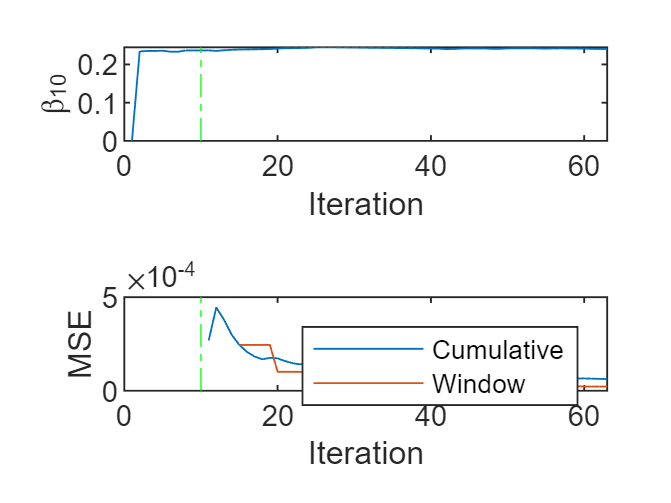


tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc = 5.3019

diff_percentage_all_inc = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc = 315×1
    3.2686
    4.6288
    5.2595
    6.2558
    6.8528
    1.5237
    1.2473
    1.3340
    0.4798
    0.1673


diff_percentage_avg_all_inc = mean(diff_percentage_all_inc,1)

diff_percentage_avg_all_inc = 2.6769

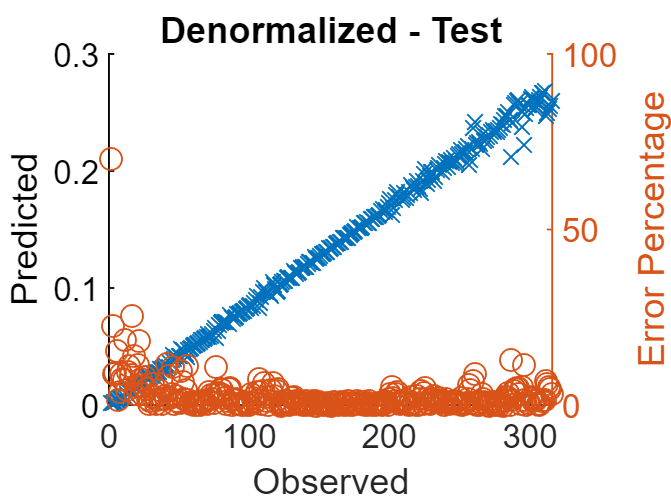

figure
hold on
plot(Ytrain_all,y_predict,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all_inc,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

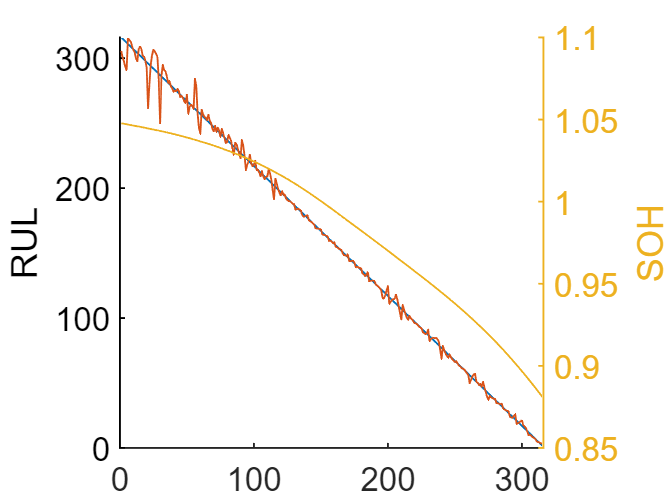


figure, hold on
plot(Y_test_RUL_test1)
plot(Y_predict)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값으로 모델 업데이트. 러닝레이트를 줄여야 한다.


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc1 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1

mdl_Linear_VdRul_fitrlinear_inc1 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1.Beta'

ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824



y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp = 5×1
    0.3864
    0.3818
    0.3792
    0.3758
    0.3734


y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1.Beta'
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp]
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1.Beta(10);
end

idx = 1×5
     6     7     8     9    10


ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4950    0.5662    0.4575    0.2428    0.0504   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2650    0.3725   -0.1075
    0.2641    0.3709   -0.1068
    0.2632    0.3702   -0.1070
    0.2624    0.3671   -0.1047
    0.2615    0.3645   -0.1030


idx = 1×5
    11    12    13    14    15


ans = 1×20
   -0.4299   -0.2471   -0.0564    0.0360    0.1613    0.3305    0.4950    0.5662    0.4575    0.2428    0.0504   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2607    0.3654   -0.1047
    0.2598    0.3614   -0.1016
    0.2590    0.3594   -0.1004
    0.2581    0.3675   -0.1093
    0.2573    0.3694   -0.1122


idx = 1×5
    16    17    18    19    20


ans = 1×20
   -0.4299   -0.2471   -0.0564    0.0361    0.1614    0.3305    0.4950    0.5662    0.4576    0.2428    0.0504   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2564    0.3573   -0.1009
    0.2556    0.3526   -0.0970
    0.2547    0.3523   -0.0976
    0.2538    0.3493   -0.0955
    0.2530    0.3447   -0.0917


idx = 1×5
    21    22    23    24    25


ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2521    0.3533   -0.1011
    0.2513    0.3692   -0.1179
    0.2504    0.3825   -0.1321
    0.2496    0.3891   -0.1395
    0.2487    0.3926   -0.1439


idx = 1×5
    26    27    28    29    30


ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2479    0.3932   -0.1453
    0.2470    0.3916   -0.1446
    0.2462    0.3896   -0.1435
    0.2453    0.3741   -0.1288
    0.2444    0.3451   -0.1006


idx = 1×5
    31    32    33    34    35


ans = 1×20
   -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2428    0.0504   -0.0923   -0.0770   -0.0033    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2436    0.3291   -0.0855
    0.2427    0.3362   -0.0935
    0.2419    0.3328   -0.0909
    0.2410    0.3320   -0.0910
    0.2402    0.3286   -0.0885


idx = 1×5
    36    37    38    39    40


ans = 1×20
   -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2429    0.0504   -0.0923   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2393    0.3268   -0.0875
    0.2385    0.3281   -0.0896
    0.2376    0.3245   -0.0869
    0.2368    0.3231   -0.0864
    0.2359    0.3209   -0.0850


idx = 1×5
    41    42    43    44    45


ans = 1×20
   -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2429    0.0504   -0.0923   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2350    0.3192   -0.0841
    0.2342    0.3185   -0.0843
    0.2333    0.3202   -0.0869
    0.2325    0.3187   -0.0863
    0.2316    0.3147   -0.0831


idx = 1×5
    46    47    48    49    50


ans = 1×20
   -0.4298   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4951    0.5663    0.4576    0.2429    0.0504   -0.0922   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2308    0.3147   -0.0839
    0.2299    0.3134   -0.0835
    0.2291    0.3110   -0.0820
    0.2282    0.3099   -0.0817
    0.2274    0.3158   -0.0884


idx = 1×5
    51    52    53    54    55


ans = 1×20
   -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2429    0.0504   -0.0923   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2265    0.3210   -0.0945
    0.2256    0.3253   -0.0997
    0.2248    0.3272   -0.1024
    0.2239    0.3263   -0.1024
    0.2231    0.3244   -0.1013


idx = 1×5
    56    57    58    59    60


ans = 1×20
   -0.4298   -0.2470   -0.0563    0.0361    0.1615    0.3306    0.4951    0.5663    0.4576    0.2429    0.0505   -0.0922   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2222    0.3213   -0.0990
    0.2214    0.3162   -0.0949
    0.2205    0.2978   -0.0773
    0.2197    0.2884   -0.0687
    0.2188    0.2845   -0.0657


idx = 1×5
    61    62    63    64    65


ans = 1×20
   -0.4298   -0.2469   -0.0563    0.0362    0.1615    0.3306    0.4951    0.5664    0.4577    0.2429    0.0505   -0.0922   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2179    0.2837   -0.0657
    0.2171    0.2807   -0.0636
    0.2162    0.2789   -0.0626
    0.2154    0.2782   -0.0629
    0.2145    0.2766   -0.0621


idx = 1×5
    66    67    68    69    70


ans = 1×20
   -0.4298   -0.2469   -0.0563    0.0362    0.1615    0.3307    0.4951    0.5664    0.4577    0.2430    0.0505   -0.0922   -0.0769   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2137    0.2728   -0.0591
    0.2128    0.2689   -0.0561
    0.2120    0.2673   -0.0553
    0.2111    0.2635   -0.0524
    0.2103    0.2616   -0.0514


idx = 1×5
    71    72    73    74    75


ans = 1×20
   -0.4297   -0.2469   -0.0563    0.0362    0.1615    0.3307    0.4951    0.5664    0.4577    0.2430    0.0505   -0.0922   -0.0769   -0.0032    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2094    0.2605   -0.0511
    0.2085    0.2564   -0.0479
    0.2077    0.2595   -0.0518
    0.2068    0.2575   -0.0506
    0.2060    0.2533   -0.0473


idx = 1×5
    76    77    78    79    80


ans = 1×20
   -0.4297   -0.2469   -0.0562    0.0362    0.1615    0.3307    0.4952    0.5664    0.4577    0.2430    0.0505   -0.0921   -0.0769   -0.0032    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans = 5×3
    0.2051    0.2543   -0.0492
    0.2043    0.2515   -0.0473
    0.2034    0.2482   -0.0448
    0.2026    0.2450   -0.0424
    0.2017    0.2454   -0.0437


idx = 1×5
    81    82    83    84    85


ans = 1×20
   -0.4297   -0.2469   -0.0562    0.0363    0.1616    0.3307    0.4952    0.5664    0.4577    0.2430    0.0506   -0.0921   -0.0769   -0.0032    0.1400   -0.0316    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.2009    0.2460   -0.0452
    0.2000    0.2440   -0.0440
    0.1991    0.2417   -0.0426
    0.1983    0.2363   -0.0380
    0.1974    0.2327   -0.0353


idx = 1×5
    86    87    88    89    90


ans = 1×20
   -0.4297   -0.2468   -0.0562    0.0363    0.1616    0.3307    0.4952    0.5664    0.4578    0.2430    0.0506   -0.0921   -0.0769   -0.0032    0.1400   -0.0316    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1966    0.2328   -0.0362
    0.1957    0.2320   -0.0363
    0.1949    0.2287   -0.0339
    0.1940    0.2255   -0.0315
    0.1932    0.2224   -0.0292


idx = 1×5
    91    92    93    94    95


ans = 1×20
   -0.4296   -0.2468   -0.0562    0.0363    0.1616    0.3308    0.4952    0.5665    0.4578    0.2430    0.0506   -0.0921   -0.0769   -0.0032    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1923    0.2195   -0.0272
    0.1915    0.2159   -0.0244
    0.1906    0.2094   -0.0188
    0.1897    0.1997   -0.0099
    0.1889    0.2030   -0.0142


idx = 1×5
    96    97    98    99   100


ans = 1×20
   -0.4296   -0.2468   -0.0561    0.0363    0.1616    0.3308    0.4952    0.5665    0.4578    0.2431    0.0506   -0.0921   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1880    0.1930   -0.0050
    0.1872    0.1974   -0.0102
    0.1863    0.1916   -0.0053
    0.1855    0.1896   -0.0042
    0.1846    0.1908   -0.0062


idx = 1×5
   101   102   103   104   105


ans = 1×20
   -0.4296   -0.2468   -0.0561    0.0363    0.1617    0.3308    0.4953    0.5665    0.4578    0.2431    0.0506   -0.0920   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1838    0.1921   -0.0083
    0.1829    0.1856   -0.0027
    0.1821    0.1860   -0.0040
    0.1812    0.1838   -0.0026
    0.1803    0.1814   -0.0011


idx = 1×5
   106   107   108   109   110


ans = 1×20
   -0.4296   -0.2467   -0.0561    0.0364    0.1617    0.3308    0.4953    0.5665    0.4578    0.2431    0.0507   -0.0920   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1795    0.1801   -0.0007
    0.1786    0.1764    0.0023
    0.1778    0.1747    0.0030
    0.1769    0.1766    0.0003
    0.1761    0.1767   -0.0007


idx = 1×5
   111   112   113   114   115


ans = 1×20
   -0.4296   -0.2467   -0.0561    0.0364    0.1617    0.3308    0.4953    0.5665    0.4579    0.2431    0.0507   -0.0920   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1752    0.1754   -0.0002
    0.1744    0.1731    0.0013
    0.1735    0.1688    0.0047
    0.1726    0.1619    0.0107
    0.1718    0.1558    0.0160


idx = 1×5
   116   117   118   119   120


ans = 1×20
   -0.4295   -0.2467   -0.0561    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2431    0.0507   -0.0920   -0.0768   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1709    0.1524    0.0185
    0.1701    0.1494    0.0207
    0.1692    0.1457    0.0235
    0.1684    0.1431    0.0253
    0.1675    0.1413    0.0263


idx = 1×5
   121   122   123   124   125


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0768   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1667    0.1421    0.0246
    0.1658    0.1396    0.0262
    0.1650    0.1400    0.0249
    0.1641    0.1370    0.0271
    0.1632    0.1362    0.0270


idx = 1×5
   126   127   128   129   130


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1624    0.1353    0.0271
    0.1615    0.1353    0.0263
    0.1607    0.1345    0.0262
    0.1598    0.1336    0.0263
    0.1590    0.1334    0.0256


idx = 1×5
   131   132   133   134   135


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1581    0.1332    0.0249
    0.1573    0.1335    0.0238
    0.1564    0.1340    0.0224
    0.1556    0.1333    0.0223
    0.1547    0.1329    0.0218


idx = 1×5
   136   137   138   139   140


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1538    0.1325    0.0214
    0.1530    0.1314    0.0216
    0.1521    0.1314    0.0207
    0.1513    0.1321    0.0192
    0.1504    0.1323    0.0181


idx = 1×5
   141   142   143   144   145


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1496    0.1322    0.0174
    0.1487    0.1316    0.0171
    0.1479    0.1312    0.0167
    0.1470    0.1303    0.0167
    0.1462    0.1293    0.0168


idx = 1×5
   146   147   148   149   150


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1453    0.1297    0.0156
    0.1444    0.1298    0.0146
    0.1436    0.1297    0.0139
    0.1427    0.1294    0.0134
    0.1419    0.1293    0.0126


idx = 1×5
   151   152   153   154   155


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1410    0.1289    0.0121
    0.1402    0.1286    0.0116
    0.1393    0.1284    0.0109
    0.1385    0.1282    0.0102
    0.1376    0.1275    0.0101


idx = 1×5
   156   157   158   159   160


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0364    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1368    0.1270    0.0098
    0.1359    0.1271    0.0088
    0.1350    0.1266    0.0084
    0.1342    0.1254    0.0088
    0.1333    0.1260    0.0073


idx = 1×5
   161   162   163   164   165


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1325    0.1261    0.0064
    0.1316    0.1255    0.0062
    0.1308    0.1251    0.0057
    0.1299    0.1243    0.0056
    0.1291    0.1243    0.0047


idx = 1×5
   166   167   168   169   170


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1282    0.1235    0.0047
    0.1274    0.1219    0.0055
    0.1265    0.1216    0.0049
    0.1256    0.1214    0.0042
    0.1248    0.1223    0.0024


idx = 1×5
   171   172   173   174   175


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1239    0.1227    0.0013
    0.1231    0.1225    0.0006
    0.1222    0.1228   -0.0006
    0.1214    0.1227   -0.0014
    0.1205    0.1215   -0.0009


idx = 1×5
   176   177   178   179   180


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1197    0.1183    0.0013
    0.1188    0.1189   -0.0001
    0.1179    0.1184   -0.0004
    0.1171    0.1180   -0.0009
    0.1162    0.1175   -0.0013


idx = 1×5
   181   182   183   184   185


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1154    0.1168   -0.0014
    0.1145    0.1164   -0.0019
    0.1137    0.1152   -0.0015
    0.1128    0.1163   -0.0034
    0.1120    0.1178   -0.0058


idx = 1×5
   186   187   188   189   190


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1111    0.1191   -0.0080
    0.1103    0.1198   -0.0096
    0.1094    0.1197   -0.0103
    0.1085    0.1200   -0.0114
    0.1077    0.1196   -0.0119


idx = 1×5
   191   192   193   194   195


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1068    0.1196   -0.0127
    0.1060    0.1191   -0.0131
    0.1051    0.1182   -0.0131
    0.1043    0.1173   -0.0131
    0.1034    0.1160   -0.0125


idx = 1×5
   196   197   198   199   200


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1026    0.1147   -0.0121
    0.1017    0.1143   -0.0126
    0.1009    0.1167   -0.0159
    0.1000    0.1197   -0.0197
    0.0991    0.1226   -0.0235


idx = 1×5
   201   202   203   204   205


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0983    0.1248   -0.0266
    0.0974    0.1261   -0.0287
    0.0966    0.1275   -0.0310
    0.0957    0.1281   -0.0323
    0.0949    0.1282   -0.0333


idx = 1×5
   206   207   208   209   210


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0940    0.1281   -0.0341
    0.0932    0.1248   -0.0317
    0.0923    0.1204   -0.0281
    0.0915    0.1156   -0.0242
    0.0906    0.1112   -0.0206


idx = 1×5
   211   212   213   214   215


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0897    0.1073   -0.0176
    0.0889    0.1039   -0.0150
    0.0880    0.1014   -0.0134
    0.0872    0.0990   -0.0119
    0.0863    0.0973   -0.0110


idx = 1×5
   216   217   218   219   220


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4580    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0855    0.0961   -0.0107
    0.0846    0.0946   -0.0100
    0.0838    0.0936   -0.0098
    0.0829    0.0923   -0.0094
    0.0821    0.0910   -0.0090


idx = 1×5
   221   222   223   224   225


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3310    0.4954    0.5666    0.4580    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0812    0.0907   -0.0095
    0.0803    0.0898   -0.0094
    0.0795    0.0886   -0.0092
    0.0786    0.0877   -0.0091
    0.0778    0.0876   -0.0098


idx = 1×5
   226   227   228   229   230


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3310    0.4954    0.5666    0.4580    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0769    0.0874   -0.0105
    0.0761    0.0866   -0.0105
    0.0752    0.0860   -0.0108
    0.0744    0.0864   -0.0120
    0.0735    0.0892   -0.0157


idx = 1×5
   231   232   233   234   235


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4580    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0726    0.0907   -0.0181
    0.0718    0.0923   -0.0205
    0.0709    0.0928   -0.0218
    0.0701    0.0932   -0.0231
    0.0692    0.0929   -0.0237


idx = 1×5
   236   237   238   239   240


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3310    0.4954    0.5666    0.4580    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0684    0.0924   -0.0240
    0.0675    0.0915   -0.0240
    0.0667    0.0899   -0.0233
    0.0658    0.0843   -0.0185
    0.0650    0.0785   -0.0135


idx = 1×5
   241   242   243   244   245


ans = 1×20
   -0.4294   -0.2465   -0.0559    0.0365    0.1618    0.3310    0.4954    0.5667    0.4580    0.2433    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0641    0.0746   -0.0105
    0.0632    0.0720   -0.0088
    0.0624    0.0695   -0.0072
    0.0615    0.0680   -0.0065
    0.0607    0.0667   -0.0060


idx = 1×5
   246   247   248   249   250


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4954    0.5667    0.4580    0.2433    0.0508   -0.0919   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0598    0.0654   -0.0056
    0.0590    0.0634   -0.0044
    0.0581    0.0622   -0.0041
    0.0573    0.0612   -0.0039
    0.0564    0.0603   -0.0039


idx = 1×5
   251   252   253   254   255


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4954    0.5667    0.4580    0.2433    0.0508   -0.0919   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0556    0.0604   -0.0048
    0.0547    0.0589   -0.0042
    0.0538    0.0574   -0.0036
    0.0530    0.0571   -0.0041
    0.0521    0.0558   -0.0036


idx = 1×5
   256   257   258   259   260


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4954    0.5667    0.4580    0.2433    0.0508   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0513    0.0546   -0.0034
    0.0504    0.0541   -0.0037
    0.0496    0.0526   -0.0030
    0.0487    0.0515   -0.0028
    0.0479    0.0503   -0.0024


idx = 1×5
   261   262   263   264   265


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4954    0.5667    0.4580    0.2433    0.0508   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0470    0.0498   -0.0028
    0.0462    0.0522   -0.0061
    0.0453    0.0544   -0.0091
    0.0444    0.0558   -0.0113
    0.0436    0.0561   -0.0126


idx = 1×5
   266   267   268   269   270


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4954    0.5667    0.4580    0.2433    0.0508   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0427    0.0561   -0.0134
    0.0419    0.0559   -0.0141
    0.0410    0.0541   -0.0131
    0.0402    0.0549   -0.0147
    0.0393    0.0530   -0.0137


idx = 1×5
   271   272   273   274   275


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0385    0.0509   -0.0124
    0.0376    0.0470   -0.0094
    0.0368    0.0440   -0.0072
    0.0359    0.0408   -0.0049
    0.0350    0.0387   -0.0037


idx = 1×5
   276   277   278   279   280


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0342    0.0388   -0.0046
    0.0333    0.0376   -0.0043
    0.0325    0.0371   -0.0046
    0.0316    0.0367   -0.0050
    0.0308    0.0365   -0.0058


idx = 1×5
   281   282   283   284   285


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0299    0.0361   -0.0061
    0.0291    0.0361   -0.0071
    0.0282    0.0356   -0.0074
    0.0274    0.0356   -0.0082
    0.0265    0.0357   -0.0092


idx = 1×5
   286   287   288   289   290


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0256    0.0349   -0.0092
    0.0248    0.0344   -0.0096
    0.0239    0.0339   -0.0100
    0.0231    0.0334   -0.0103
    0.0222    0.0331   -0.0109


idx = 1×5
   291   292   293   294   295


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0214    0.0328   -0.0114
    0.0205    0.0326   -0.0120
    0.0197    0.0322   -0.0125
    0.0188    0.0335   -0.0147
    0.0179    0.0346   -0.0167


idx = 1×5
   296   297   298   299   300


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0171    0.0356   -0.0185
    0.0162    0.0359   -0.0197
    0.0154    0.0365   -0.0212
    0.0145    0.0373   -0.0228
    0.0137    0.0380   -0.0243


idx = 1×5
   301   302   303   304   305


ans = 1×20
   -0.4293   -0.2465   -0.0559    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0128    0.0381   -0.0252
    0.0120    0.0374   -0.0254
    0.0111    0.0362   -0.0251
    0.0103    0.0336   -0.0234
    0.0094    0.0313   -0.0219


idx = 1×5
   306   307   308   309   310


ans = 1×20
   -0.4293   -0.2465   -0.0558    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0085    0.0292   -0.0207
    0.0077    0.0284   -0.0207
    0.0068    0.0274   -0.0206
    0.0060    0.0270   -0.0210
    0.0051    0.0263   -0.0211


idx = 1×5
   311   312   313   314   315


ans = 1×20
   -0.4293   -0.2465   -0.0558    0.0366    0.1619    0.3310    0.4955    0.5667    0.4580    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2708   -0.4946   -0.4823


ans = 5×3
    0.0043    0.0266   -0.0224
    0.0034    0.0262   -0.0227
    0.0026    0.0260   -0.0234
    0.0017    0.0254   -0.0237
    0.0009    0.0251   -0.0243


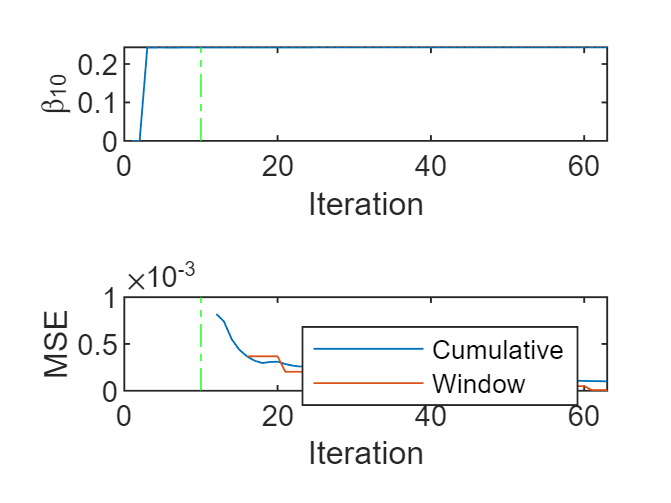


tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1 = 57.1364

diff_percentage_all_inc1 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1 = 315×1
   43.3669
   42.1212
   41.6242
   40.7826
   40.3368
   40.4520
   40.2984
   40.4978
   39.7640
   39.2403


diff_percentage_avg_all_inc1 = mean(diff_percentage_all_inc1,1)

diff_percentage_avg_all_inc1 = 42.0479

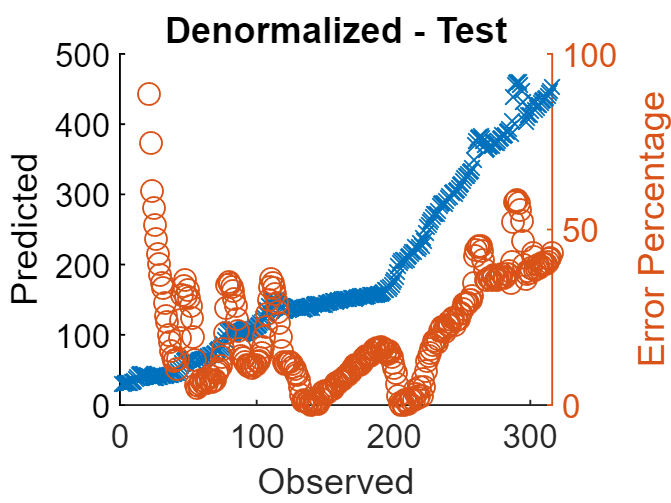

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all_inc1,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

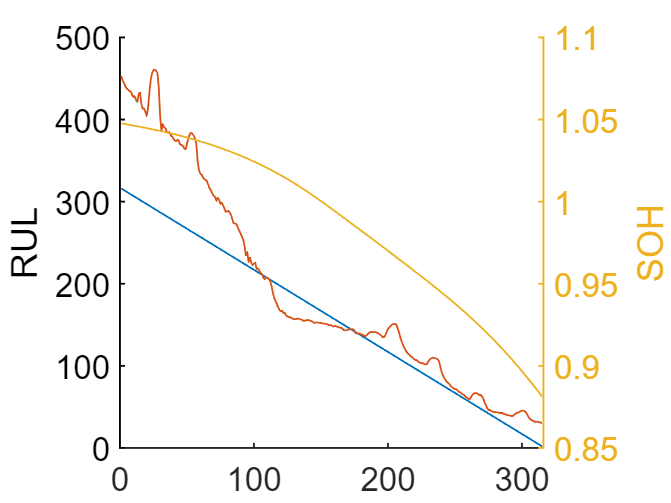



figure, hold on
plot(Y_test_RUL_test1)
plot(Y_predict)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값과 가장 비슷한 패턴의 다른 데이타로 모델 업데이트. 러닝레이트를 줄여야 한다.




maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc2 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc2

mdl_Linear_VdRul_fitrlinear_inc2 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
%mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc2.Beta'

ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824




y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp = 5×1
    0.3864
    0.3818
    0.3792
    0.3758
    0.3734


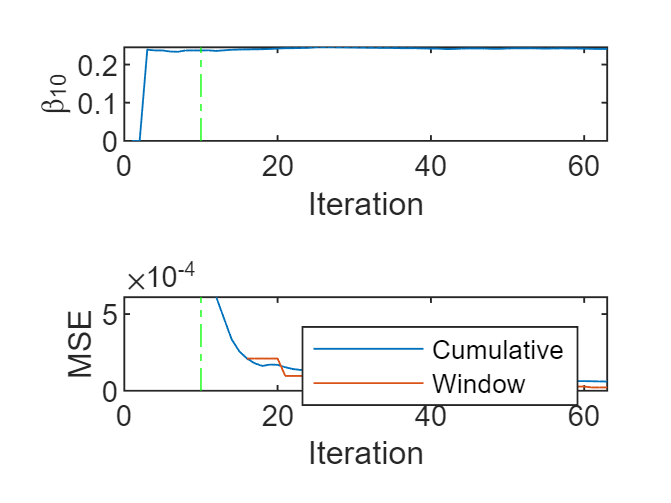

y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   ;


    % y_update = ytrain(idx);
    y_update = ( ytrain(idx) + y_predict_temp ) /2 ;

    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc2 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc2, ...
        Xtrain(idx,:), ...
        y_update); %  
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc2.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp];
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc2.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc2 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc2 = 19.9533

diff_percentage_all_inc2 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc2 = 315×1
   43.3669
   42.1212
   41.6242
   40.7826
   40.3368
   20.2352
   20.0178
   20.1587
   19.3623
   18.7744


diff_percentage_avg_all_inc2 = mean(diff_percentage_all_inc2,1)

diff_percentage_avg_all_inc2 = 10.2005

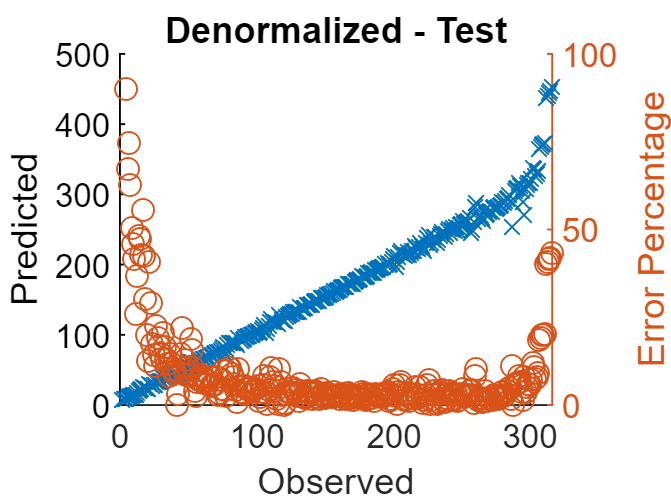

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all_inc2,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

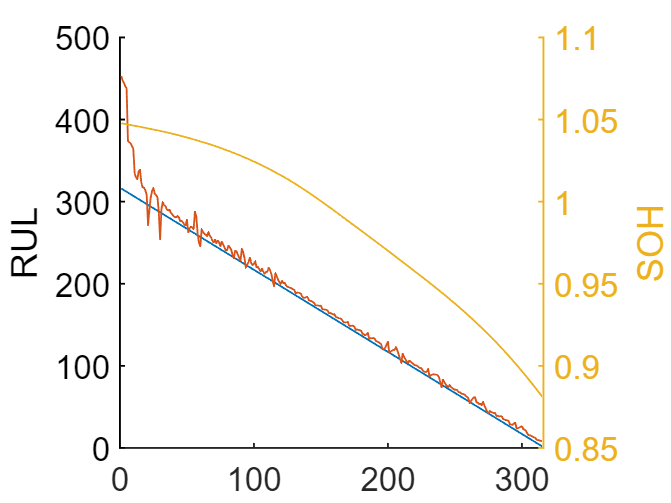



figure, hold on
plot(Y_test_RUL_test1)
plot(Y_predict)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

## 현재까지의 자기 데이타로 학습/예측 - 실제적이지 않다. - 오차 적음


result_pre_summary = table(rmse_pre,diff_percentage_avg_pre);
result_pre_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_pre_summary

result_pre_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    14.091      4.2072  


## 현재까지의 자기 데이타로 학습/이후 예측 - 오차 큼


result_future_summary = table(rmse_future,diff_percentage_avg_future);
result_future_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_future_summary

result_future_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    169.43      454.05  


## 다른 데이타들로 학습 후 자기 데이타로 예측 - 일반적 시나리오 - 오차 보통


result_all_summary = table(rmse_all,diff_percentage_avg_all);
result_all_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_summary

result_all_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    56.308      32.748  


## 기본 모델은 클라우드에서 학습한 것. 점진적 학습. 자신의 미래 RUL을 확신하는 경우 - 오차 적음. 학습비율 크게.


result_all_inc_summary = table(rmse_all_inc,diff_percentage_avg_all_inc);
result_all_inc_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc_summary

result_all_inc_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    5.3019      2.6769  


## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율 작게 


result_all_inc1_summary = table(rmse_all_inc1,diff_percentage_avg_all_inc1);
result_all_inc1_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1_summary

result_all_inc1_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    57.136      42.048  


## 5개의 예측값과 비슷한 다른 데이타의 5개 값을 이용 모델 갱신 -오차 작음


result_all_inc2_summary = table(rmse_all_inc2,diff_percentage_avg_all_inc2);
result_all_inc2_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc2_summary

result_all_inc2_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    19.953      10.201  


% https://kr.mathworks.com/help/matlab/matlab_prog/limitations-of-tables-and-timetables.html

mape_pre       =  diff_percentage_avg_pre        ;
mape_future    =  diff_percentage_avg_future     ;
mape_all       =  diff_percentage_avg_all        ;
mape_all_inc   =  diff_percentage_avg_all_inc    ;
mape_all_inc1  =  diff_percentage_avg_all_inc1   ;
mape_all_inc2  =  diff_percentage_avg_all_inc2   ;

rmse_list = [ rmse_pre ; rmse_future ; rmse_all ; rmse_all_inc ; rmse_all_inc1 ; rmse_all_inc2 ]

rmse_list =    14.0912
  169.4288
   56.3081
    5.3019
   57.1364
   19.9533


mape_list = [ mape_pre ; mape_future ; mape_all ; mape_all_inc ; mape_all_inc1 ; mape_all_inc2 ]

mape_list =     4.2072
  454.0499
   32.7476
    2.6769
   42.0479
   10.2005


scenario_list = ["scenario 1" ; "scenario 2" ;"scenario 3";"scenario 4";"scenario 5";"scenario 6"]

scenario_list = 6×1 string array
    "scenario 1"
    "scenario 2"
    "scenario 3"
    "scenario 4"
    "scenario 5"
    "scenario 6"


scenario_index_list = ["1" ; "2" ;"3";"4";"5";"6"]

scenario_index_list = 6×1 string array
    "1"
    "2"
    "3"
    "4"
    "5"
    "6"


RowNames = {'scenario 1','scenario 2','scenario 3','scenario 4','scenario 5','scenario 6'}

RowNames = 1×6 cell array
    {'scenario 1'}    {'scenario 2'}    {'scenario 3'}    {'scenario 4'}    {'scenario 5'}    {'scenario 6'}


VariableNames = {'Scenario #','RMSE','MAPE'}

VariableNames = 1×3 cell array
    {'Scenario #'}    {'RMSE'}    {'MAPE'}


VariableNames1 = {'RMSE','MAPE'}

VariableNames1 = 1×2 cell array
    {'RMSE'}    {'MAPE'}



result_NoChange = table( scenario_list, rmse_list , mape_list , 'VariableNames',VariableNames);
result_NoChange.Properties.Description = 'Test Result : Without Patten Change';
result_NoChange.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : Without Patten Change'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Scenario #'  'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_NoChange.Properties.RowNames = scenario_list;
result_NoChange

result_NoChange = 6×3 table
                   Scenario #      RMSE      MAPE 
                  ____________    ______    ______

    scenario 1    "scenario 1"    14.091    4.2072
    scenario 2    "scenario 2"    169.43    454.05
    scenario 3    "scenario 3"    56.308    32.748
    scenario 4    "scenario 4"    5.3019    2.6769
    scenario 5    "scenario 5"    57.136    42.048
    scenario 6    "scenario 6"    19.953    10.201



result_NoChange1 = table( rmse_list , mape_list , 'VariableNames',VariableNames1); %,'RowNames',RowNames)
result_NoChange1.Properties.Description = 'Test Result : Without Patten Change';
result_NoChange1.Properties.RowNames = scenario_list

result_NoChange1 = 6×2 table
                   RMSE      MAPE 
                  ______    ______

    scenario 1    14.091    4.2072
    scenario 2    169.43    454.05
    scenario 3    56.308    32.748
    scenario 4    5.3019    2.6769
    scenario 5    57.136    42.048
    scenario 6    19.953    10.201


result_NoChange1.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : Without Patten Change'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {6×1 cell}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_NoChange1

result_NoChange1 = 6×2 table
                   RMSE      MAPE 
                  ______    ______

    scenario 1    14.091    4.2072
    scenario 2    169.43    454.05
    scenario 3    56.308    32.748
    scenario 4    5.3019    2.6769
    scenario 5    57.136    42.048
    scenario 6    19.953    10.201


% load patients
% T = table(Gender,Age,Height,Weight,Smoker,Systolic,Diastolic)



% http://matlab.izmiran.ru/help/toolbox/nnet/model211.html


p1 = [-1  0 1 0 1 1 -1  0 -1 1 0 1];
t1 = [-1 -1 1 1 1 2  0 -1 -1 0 1 1 ];
net = linearlayer([0 1],0.1)
[net,y,e,pf] = adapt(net,p1,t1)
%clear mse
mse(e)

net =

    Neural Network
 
              name: 'Linear Neural Layer'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 1
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: tr

% https://kr.mathworks.com/matlabcentral/answers/269435-what-is-the-difference-between-the-regress-function-and-the-fitlm-function

net =

    Neural Network
 
              name: 'Linear Neural Layer'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 1
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: tr

y = 1×12
     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×12
    -1    -1     1     1     1     2     0    -1    -1     0     1     1


pf = 1×12
    -1     0     1     0     1     1    -1     0    -1     1     0     1


% The key difference is intercept: 1. "fitlm(x,y)" function uses intercept by default 2. "regress(y,x)" function uses no intercept by default (you can add intercept by adding "ones" matrix)


ans = 1.0833

% https://kr.mathworks.com/help/stats/fitrlinear.html
% fitrlinear
% Fit linear regression model to high-dimensional data


%Alternatives for Lower-Dimensional Data
%High-dimensional linear classification and regression models minimize objective functions relatively quickly, but at the cost of some accuracy, the numeric-only predictor variables restriction, and the model must be linear with respect to the parameters. If your predictor data set is low- through medium-dimensional, or contains heterogeneous variables, then you should use the appropriate classification or regression fitting function. To help you decide which fitting function is appropriate for your low-dimensional data set, use this table.

% Model to Fit	Function	Notable Algorithmic Differences
% SVM	
% Binary classification: fitcsvm
% 
% Multiclass classification: fitcecoc
% 
% Regression: fitrsvm
% 
% Computes the Gram matrix of the predictor variables, which is convenient for nonlinear kernel transformations.
% 
% Solves dual problem using SMO, ISDA, or L1 minimization via quadratic programming using quadprog (Optimization Toolbox).
% 
% Linear regression	
% Least-squares without regularization: fitlm
% 
% Regularized least-squares using a lasso penalty: lasso
% 
% Ridge regression: ridge or lasso
% 
% lasso implements cyclic coordinate descent.
% 
% Logistic regression	
% Logistic regression without regularization: fitglm.
% 
% Regularized logistic regression using a lasso penalty: lassoglm
% 
% fitglm implements iteratively reweighted least squares.
% 
% lassoglm implements cyclic coordinate descent.



% https://kr.mathworks.com/help/stats/incrementalregressionlinear.html
% Description
% incrementalRegressionLinear creates an incrementalRegressionLinear model object, which represents an incremental linear model for regression problems. Supported learners include support vector machine (SVM) and least squares.
% 
% Unlike other Statistics and Machine Learning Toolbox™ model objects, incrementalRegressionLinear can be called directly. Also, you can specify learning options, such as performance metrics configurations, parameter values, and the objective solver, before fitting the model to data. After you create an incrementalRegressionLinear object, it is prepared for incremental learning.
% 
% incrementalRegressionLinear is best suited for incremental learning. For a traditional approach to training an SVM or linear regression model (such as creating a model by fitting it to data, performing cross-validation, tuning hyperparameters, and so on), see fitrsvm or fitrlinear.
% 
% 
% https://kr.mathworks.com/help/stats/regressionlinear-class.html
% Construction
% Create a RegressionLinear object by using fitrlinear.

% codegen common file
gen_code = false

gen_code = logical
   0


load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

cfg = coder.config('lib','ecoder',false);
cfg.GenCodeOnly = true;
cfg.HardwareImplementation.ProdHWDeviceType = 'ARM Compatible->ARM Cortex';


Xtrain_one_sample = Xtrain(1,:)

Xtrain_one_sample =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011



predictorData = coder.typeof(Xtrain(1:5,:)); 
responseData = coder.typeof(ytrain(1:5));
observedData = coder.typeof(ytrain(1:5));



if gen_code

scenario_12_Mdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: 0.2473
               Lambda: 0.0200
              Learner: 'leastsquares'


  Properties, Methods


scenario_12_Mdl = Mdl1
%saveLearnerForCoder(scenario_12_Mdl,'scenario_12_Mdl');
saveLearnerForCoder(scenario_12_Mdl,'InitialLinearMdl');


configurer12 =   RegressionLinearCoderConfigurer with properties:

   Update Inputs:
              Beta: [1×1 LearnerCoderInput]
              Bias: [1×1 LearnerCoderInput]

   Predict Inputs:
                 X: [1×1 LearnerCoderInput]

   Code Generation Parameters:
        NumOutputs: 1
    OutputFileName: 'RegressionLinearModel'


  Properties, Methods


configurer12 = learnerCoderConfigurer(scenario_12_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
%configurer12.OutputFileName = 'scenario_12_Mdl'

generateCode creates these files in output folder:
'initialize.m', 'predict.m', 'update.m', 'RegressionLinearModel.mat'
Code generation successful.



generateCode(configurer12,cfg,'OutputPath','scenario_12_Mdl')
end

% at first, please delete existing root folder, to delete already generated
%  m files.

if gen_code

ans =    -0.4300
   -0.2471
   -0.0565
    0.0360
    0.1613
    0.3305
    0.4949
    0.5662
    0.4575
    0.2428


mdl_Linear_VdRul_fitrlinear.Beta

scenario_3_Mdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


scenario_3_Mdl = mdl_Linear_VdRul_fitrlinear
saveLearnerForCoder(scenario_3_Mdl,'InitialLinearMdl');

configurer3 =   RegressionLinearCoderConfigurer with properties:

   Update Inputs:
              Beta: [1×1 LearnerCoderInput]
              Bias: [1×1 LearnerCoderInput]

   Predict Inputs:
                 X: [1×1 LearnerCoderInput]

   Code Generation Parameters:
        NumOutputs: 1
    OutputFileName: 'RegressionLinearModel'


  Properties, Methods


configurer3 = learnerCoderConfigurer(scenario_3_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')

Specified folder does not exist. Folder has been created.
generateCode creates these files in output folder:
'initialize.m', 'predict.m', 'update.m', 'RegressionLinearModel.mat'
Code generation successful.



generateCode(configurer3,cfg,'OutputPath','scenario_3_Mdl')
end

if gen_code
%load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

scenario_4_Mdl = mdl_Linear_VdRul_fitrlinear_inc
scenario_5_Mdl = mdl_Linear_VdRul_fitrlinear_inc1
scenario_6_Mdl = mdl_Linear_VdRul_fitrlinear_inc2
end

if gen_code 
 saveLearnerForCoder(scenario_4_Mdl,'scenario_4_Mdl');
 saveLearnerForCoder(scenario_5_Mdl,'scenario_5_Mdl');
 saveLearnerForCoder(scenario_6_Mdl,'scenario_6_Mdl');
end
 

% https://kr.mathworks.com/help/stats/classreg.learning.coder.config.svm.classificationsvmcoderconfigurer.generatecode.html
%cfg.CustomFileNameStr = 'sc3';

% configurer4 = learnerCoderConfigurer(scenario_4_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
% configurer4.OutputFileName = 'scenario_4_Mdl'
% generateCode(configurer4,cfg,'OutputPath','scenario_4_Mdl')

if gen_code


IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_4_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_5_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
% copy m files to current dir
codegen -config cfg  -d scenario_6_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

거의 다 했다. 

- 된것 

- 매트랩에서 시뮬레이션 한것.

- 안된것 